clc; clear; close all; 
save_data= true;

A0=13/10+1;
f0=13/8+10;

A1= 0.19*A0;
f1= 0.13*f0;

A2= 0.23*A0;
f2= 20*f0;

A3= 0.14*A0;
f3= 42*f0;

fs= 10*max([f0,f1,f2,f3]);
dt= 1/fs;

T=10;
df=1/T;

N=T/dt;

t_vec= (0:N-1)' * dt;
f_vec= (0:N-1)' * df;

s0= A0* sin(2*pi*f0*t_vec);
s1= A1* sin(2*pi*f1*t_vec);
s2= A2* sin(2*pi*f2*t_vec);
s3= A3* sin(2*pi*f3*t_vec);
s_0123= sum([s0,s1,s2,s3],2);

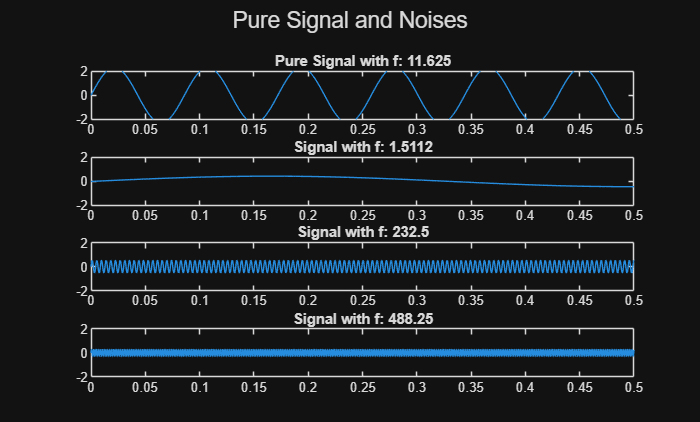

figure 
sgtitle('Pure Signal and Noises')

subplot(4,1,1)
plot(t_vec,s0)
title("Pure Signal with f: "+f0)

subplot(4,1,2)
plot(t_vec,s1)
title("Signal with f: "+f1)

subplot(4,1,3)
plot(t_vec,s2)
title("Signal with f: "+f2)

subplot(4,1,4)
plot(t_vec,s3)
title("Signal with f: "+f3)

ax=findall(gcf, 'Type', 'axes');
linkaxes(ax, 'xy');
xlim([0 0.5]);
ylim([-2 2]);

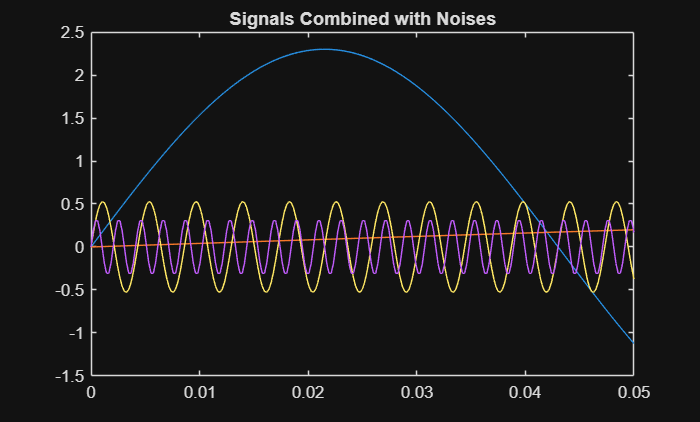

figure 
plot(t_vec,[s0 s1 s2 s3])
title('Signals Combined with Noises')
xlim([0 0.05])

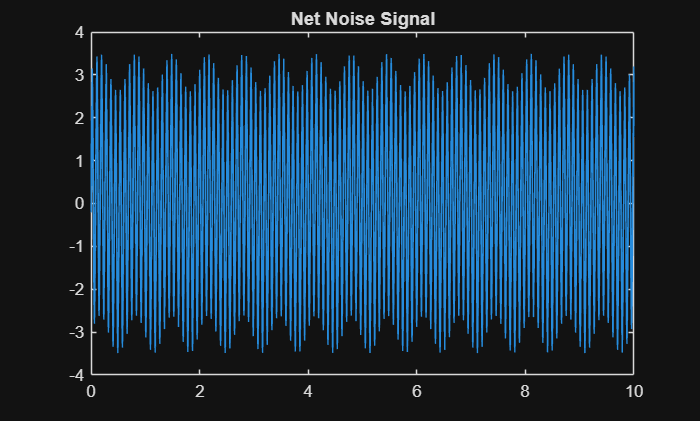


figure
plot(t_vec,s_0123)
title('Net Noise Signal')

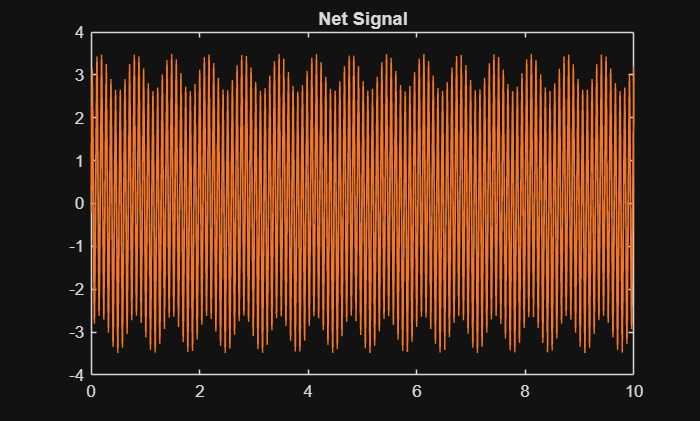


figure 
plot(t_vec,[s0 s_0123])
title('Net Signal')

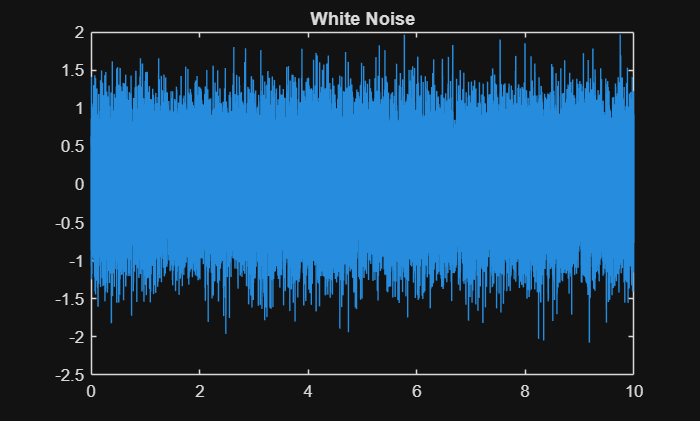

std_dev= 0.22;
wgn= std_dev*A0*randn(size(t_vec));

figure 
plot(t_vec,wgn)
title('White Noise')

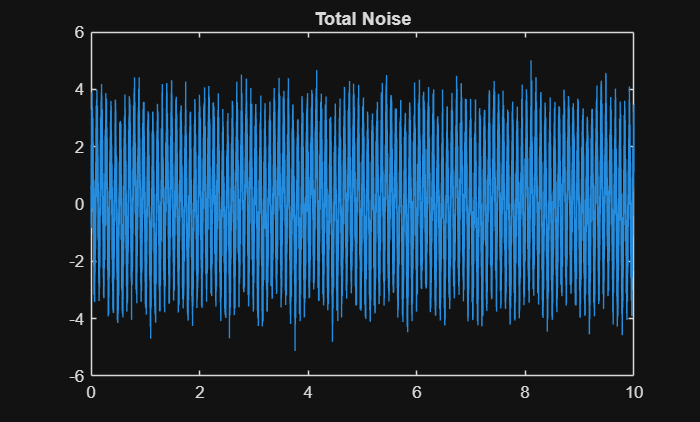


s_0123_r= s_0123+wgn;

figure 
plot(t_vec,s_0123_r)
title('Total Noise')

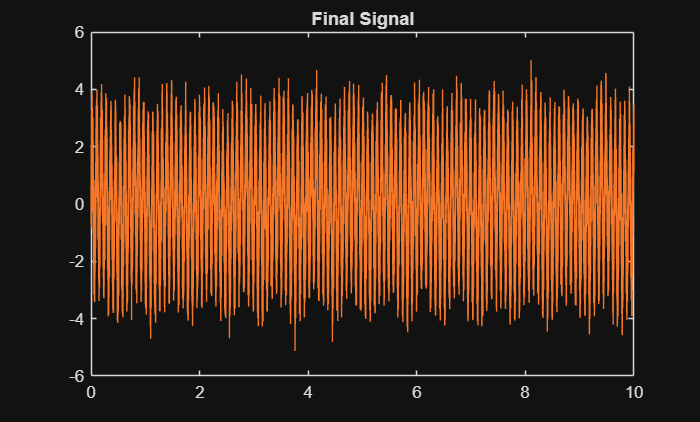


figure
plot(t_vec,[s0 s_0123_r])
title('Final Signal')

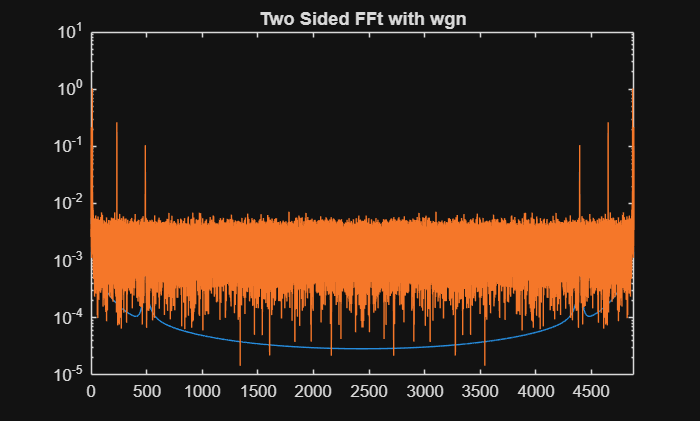

y= fft([s0 s1 s2 s3 s_0123 s_0123_r]);
p2= abs(y/N);
p2= round(p2,16);

figure 
semilogy(f_vec,p2(:,5:6))
title('Two Sided FFt with wgn')
xlim([0 fs])

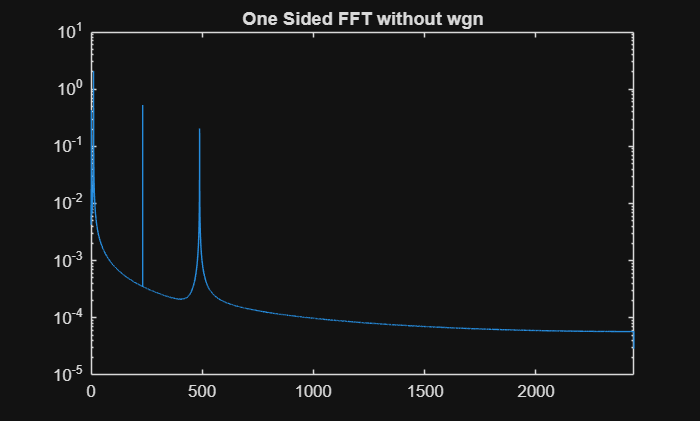

f_vec_1side= 0:df:fs/2;
p1= p2(1:floor(N/2)+1,:);
p1(2:end-1,:)= 2*p1(2:end-1,:);

figure
semilogy(f_vec_1side,p1(:,5))
title('One Sided FFT without wgn')
xlim([0 fs/2])

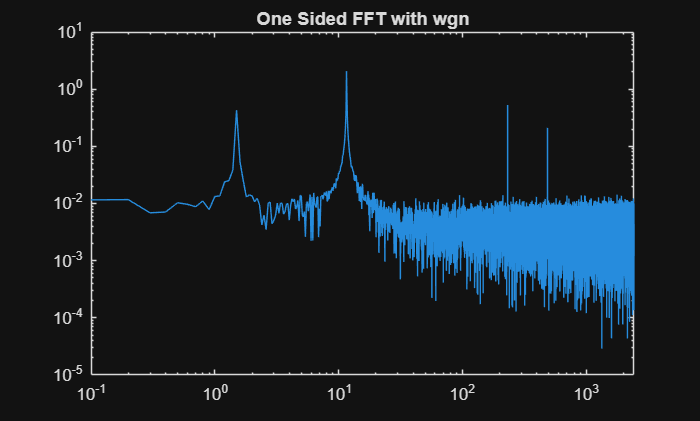


figure 
loglog(f_vec_1side,p1(:,6))
title('One Sided FFT with wgn')
xlim([0 fs/2])

if save_data
    writematrix([t_vec s_0123_r],'noisy_signal_time.txt')
    writematrix([t_vec s0],'pure_signal_time.txt')
    writematrix([t_vec s0 s_0123 s_0123_r],'time_pure_purenBD_purenBDRand.txt')
end